% === 参数设置 ===
close all; clear; clc
j = sqrt(-1);

fs = 80e6;           % 采样频率
ts = 1/fs;
B = 10e6;            % 带宽
fc = 40e6;           % 中心频率
label = 15;

% === LFM脉冲 ===
taup = 10e-6;        % LFM脉宽
Ntau = round(taup * fs);
ttau = (-Ntau/2 : Ntau/2-1) * ts;
lfm = exp(1j*pi*B/taup * ttau.^2);  % 基带LFM脉冲

% === 多脉冲参数 ===
Np = 16;                 % 脉冲个数
PRI = 200e-6;            % 脉冲重复间隔 200 μs
PRI_samp = round(PRI * fs);   % 每个PRI的采样点
N_total = Np * PRI_samp;      % 总采样点数
t_total = (0:N_total-1) * ts; % 时间轴

% === 构造发射信号 ===
tx = zeros(1, N_total);
target_start_idx_in_PRI = 5e3

target_start_idx_in_PRI = 5000

for k = 0:Np-1
    start_idx = k * PRI_samp + target_start_idx_in_PRI;
    tx(start_idx : start_idx + Ntau - 1) = lfm;
end

% === 模拟噪声与干扰 ===
SNR = 15;
JNR = 15;
Bj = 5e6;  % 扫频带宽
fjc = 0;   % 干扰中心频率
data_num = 3 %干扰样本数

data_num = 3

As = 10^(SNR/20);
Aj = 10^(JNR/20);

jam = zeros(data_num,N_total);
repetition_times_arr=[4,3,2,1];   %重复次数
period_arr=[5e-6,10e-6];    %采样脉冲周期 taup / period = 4 或 2，表示采样次数
duty_arr=[20,25,33.33,50];  %占空比

for m = 1:data_num
        sp = randn([1,N_total]) + 1j*randn([1,N_total]);
    sp = sp / std(sp);
    white_noise = sp;
    % --- 1. 生成用于卷积的噪声源 ---
    % 这个噪声是干扰机内部产生的，用于生成干扰信号
    % 其长度应足够长以进行有效的卷积
    convolution_noise = randn([1, PRI_samp]) + 1j*randn([1, PRI_samp]);
    convolution_noise = convolution_noise / std(convolution_noise);
    
    % --- 2. 创建卷积核 (间歇采样的LFM信号) ---
    % 设置间歇采样的随机参数
    sampling_period = taup / (5 + randi(10)); % 采样周期
    sampling_duty = 20 + randi(30);           % 占空比
    
    % 生成单极性方波门控信号
    squa = (square((1/sampling_period)*2*pi*ttau, sampling_duty) + 1) / 2;
    % 将LFM信号与门控相乘，得到卷积核
    jam_kernel = lfm .* squa;
    
    % --- 3. 执行卷积 ---
    % 将噪声源与卷积核进行卷积
    % 'same' 选项确保输出长度与第一个输入 (噪声) 相同
    jam_conv_result = conv(convolution_noise, jam_kernel, 'same');

    % --- 4. 在一个PRI内生成转发干扰串 ---
    % 我们首先在一个PRI内生成干扰，然后将其复制到所有PRI
    jam_pri = zeros(1, PRI_samp);
    repetition_times = 5 + randi(5); % 转发5-10次

    for i = 1:repetition_times
        % 设置每次转发的随机延迟 (e.g., 1us to 5us)
        delay_time = (1 + rand() * 4) * 1e-6; 
        delay_samp = round(delay_time * fs);
        
        % 干扰切片的起始位置
        if i == 1
            left_range = target_start_idx_in_PRI + delay_samp;
        else
            left_range = last_pos + delay_samp;
        end
        right_range = left_range + Ntau - 1;
        
        last_pos = left_range; % 记录位置供下次使用
        
        % 检查是否超出当前PRI的范围
        if right_range <= PRI_samp
            % 从卷积结果中取出一个脉宽长度的片段作为干扰信号
            % 为了增加随机性，可以从jam_conv_result的不同位置开始取
            start_point = randi(length(jam_conv_result) - Ntau);
            jam_segment = jam_conv_result(start_point : start_point + Ntau - 1);
            
            % 为每次转发设置一个随机幅度
            Aj_rand = Aj * (0.5 + rand()); 
            jam_pri(left_range:right_range) = jam_pri(left_range:right_range) + Aj_rand * jam_segment;
        end
    end

    % --- 4. 将单个PRI的干扰模板复制到整个信号长度 ---
    
    
    jam_signal(1,:) = repmat([jam_pri ,zeros(1,2*PRI_samp) ],1, 6)
    jam_signal(2,:) = repmat([zeros(1,PRI_samp),jam_pri,zeros(1,PRI_samp)],1, 6)
    jam_signal(3,:) = repmat([zeros(1,2*PRI_samp),jam_pri],1, 6)
    
    
    jam(m, :) = jam_signal(m,1:N_total)+sp;

end

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

jam_signal = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0

    % --- 5. 保存生成的干扰样本 ---
    figure;
    for i =1:3
        subplot(3,1,i)
        
        j_max= max(real(jam(i, :)))

    plot(t_total*1e3,jam(i, :))
    title("干扰源"+num2str(i));
            axis([0 3.2 -1*j_max j_max])
xlabel('时间/ms','FontSize',10); ylabel('幅度','FontSize',10);set(gca,'FontName','宋体');
    end

j_max = 461.4400

j_max = 281.5160

j_max = 307.3770

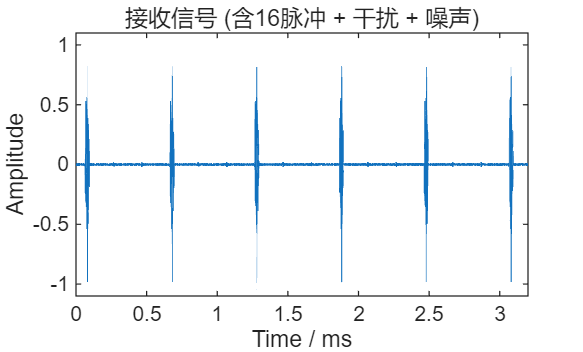

    set(gcf,'PaperUnits','centimeters');
set(gcf,'PaperPosition',[0 0 15 9]);   % 宽14cm，高7cm
set(gcf,'PaperSize',[15 9]);
save_path = 'D:\VScode\Blind_Source_Seperation\pic_ICA'; % 修改为你的路径

filename = fullfile(save_path, ['EXP-16-FJ' '.emf']);
print(gcf, filename, '-dmeta','-r300');
% --- 加入目标与干扰 ---
range_tar = 1 + round(rand(1)*4000);
pure_echo = As*tx;
rx = As*tx + jam(1,:) + white_noise;
rx = rx / max(abs(rx));

figure;
plot(t_total*1e3, real(rx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');
title('接收信号 (含16脉冲 + 干扰 + 噪声)');

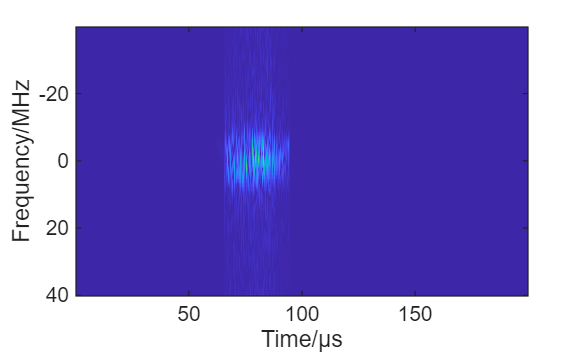


figure;
[S,F,T] = spectrogram(rx(1:PRI_samp),32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
% axis([0 100 -20 20])
ylabel('Frequency/MHz'); xlabel('Time/μs');


% === 匹配滤波（脉冲压缩） ===
h = conj(flip(lfm));
y = conv(rx, h);
env = abs(y);

% === 脉冲积累（非相干示例） ===
env_mat = reshape(env(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
env_sum = abs(sum(env_mat, 2));  % 直接复数相加再取幅度
nenv_mat = reshape(y(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
nenv_sum = sum(nenv_mat, 2); % 非相干积累

% 距离轴
c = 3e8;
rng_axis = (0:PRI_samp-1)*c/(2*fs);





